# Three Disk Oscillator

clear
close all
clc

## State space representation

% Define states as symbols
syms J_1 J_2 J_3 k_1 k_2 b_1 b_2 b_3 
syms theta_1 theta_2 theta_3 omega_1 omega_2 omega_3 u_1 u_2 d 

% Write system equations
eq1 = omega_1;
eq2 = 1/J_1 * (u_1 - b_1*omega_1 - k_1 * (theta_1 - theta_2) - d);
eq3 = omega_2;
eq4 = 1/J_2 * (u_2 - b_2 * omega_2 - k_1*(theta_2 - theta_1) - k_2*(theta_2-theta_3));
eq5 = omega_3;
eq6 = 1/J_3 * (-b_3 * omega_3 - k_2*(theta_3 - theta_2));

y_1 = theta_1;
y_2 = theta_2;
y_3 = theta_3;



A = ((jacobian([eq1, eq2, eq3, eq4, eq5, eq6],[theta_1, omega_1, theta_2, omega_2, theta_3, omega_3])))

$$A = \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ -\frac{k_{1}}{J_{1}} & -\frac{b_{1}}{J_{1}} & \frac{k_{1}}{J_{1}} & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ \frac{k_{1}}{J_{2}} & 0 & -\frac{k_{1}+k_{2}}{J_{2}} & -\frac{b_{2}}{J_{2}} & \frac{k_{2}}{J_{2}} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & \frac{k_{2}}{J_{3}} & 0 & -\frac{k_{2}}{J_{3}} & -\frac{b_{3}}{J_{3}} \end{array}\right)$$

B = ((jacobian([eq1, eq2, eq3, eq4, eq5, eq6],[u_1, u_2])))

$$B = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{J_{1}} & 0\\ 0 & 0\\ 0 & \frac{1}{J_{2}}\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

C = ((jacobian([y_1; y_2; y_3],[theta_1, omega_1, theta_2, omega_2, theta_3, omega_3])))

$$C = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 \end{array}\right)$$

D = ((jacobian([y_1; y_2; y_3], [u_1, u_2])))

$$D = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$


Ex = ((jacobian([eq1, eq2, eq3, eq4, eq5, eq6], d)))

$$Ex = \left(\begin{array}{c} 0\\ -\frac{1}{J_{1}}\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Ey = ((jacobian([y_1; y_2; y_3], d)))

$$Ey = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


% Fx = vpa((jacobian([eq1,eq2, eq3, eq4, eq5, eq6],[f_1, f_2, f_3, f_4, f_5])),3)
% Fy = vpa((jacobian([y_1; y_2; y_3; y_4; y_5],[f_1, f_2, f_3, f_4, f_5])),3)


## Load values

Load values

clear

addpath('./Data')
addpath('./Models')

load('ECP_values.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                     % Threshold angular velocity rad/s

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
sigma_meas = 0.0093*eye(3);     % Measurements covariance matrix


## Write numeric matrices

A = [0, 1, 0, 0, 0, 0; 
    -k_1/J_1, -b_1/J_1, k_1/J_1, 0, 0, 0; 
    0,0,0, 1,0,0; 
    k_1/J_2, 0, -(k_1 + k_2)/J_2, -b_2/J_2, k_2/J_2, 0; 
    0,0,0,0,0,1; 
    0,0, k_2/J_3, 0, -k_2/J_3, -b_3/J_3];

B = [0,0;
    1/J_1, 0; 
    0,0; 
    0,1/J_2; 
    zeros(2)];

C = [1, zeros(1,5); 0,0,1,zeros(1,3); zeros(1,4), 1, 0]; 
D = zeros(3,2); 
Ex = [0; -1/J_1; zeros(4,1)]; 
Ey = zeros(3,1);

## Residual generator

I now use:

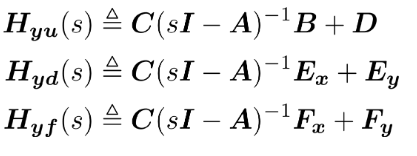

% sys = ss(A,B,C,D);
% H_yu = tf(sys)
% % [n_yu,d_yu] = ss2tf(A,B,C,D)
% 
% sys_dist = ss(A,Ex,C,Ey);
% H_yd = tf(sys_dist)
% % [n_yd,d_yd] = ss2tf(A,E_x,C,E_y)
% 
% H = [H_yu, H_yd; eye(2), zeros(2,1)]
% 
% F = null(H')'

## Symbolic

% syms s
% 
% Hyu = C/(s*eye(length(A)) - A)*B + D;
% Hyd = C/(s*eye(length(A)) - A)*Ex + Ey;
% 
% H = [Hyu Hyd; eye(2) zeros(2,1)];       % Construct H(s)
% F = simplify(null(H')');    % Obtain the left nullspace basis
% % 
% % 
% % % Determine residual generator
% Vry = F(:,1:size(C,1));
% Vru = F(:,size(C,1)+1 : end);
% % 
% Vry * Hyd
% % 
% % % Second order low pass filter
% % syms omega_n zeta
% omega_n = 1;
% zeta = 0.9;
% Q = [1, 0; 0, omega_n^2/(s^2 + 2 * zeta * omega_n * s + omega_n^2)]; % Define the filter
% % Q = omega_n^2/(s^2 + 2 * zeta * omega_n * s + omega_n^2) * eye(2); % Define the filter
% % 
% % 
% F = simplify(Q*F); % Apply filter to F(s)
% % 
% % 
% syms y_1 y_2 y_3 u_1 u_2
% r = simplify(F * [y_1, y_2, y_3, u_1, u_2].')
% 
% 
% % 
% % r = ([1; Q(2,2)] .* r)


$$\begin{array}{l}
r_1 =\theta {\;}_3 -\frac{k_2 \theta {\;}_2 }{J_3 s^2 +b_3 s+k_2 }\\
r_2 =u_2 \frac{\omega {\;}_n^2 }{s^2 +2\zeta \;\omega {\;}_n s+\omega {\;}_n^2 }+k_1 \theta {\;}_1 \frac{\omega {\;}_n^2 }{s^2 +2\zeta \;\omega {\;}_n s+\omega {\;}_n^2 }-\frac{\omega {\;}_n^2 }{s^2 +2\zeta \;\omega {\;}_n s+\omega {\;}_n^2 }\frac{J_2 J_3 s^4 +\left(J_2 b_3 +J_3 b_2 \right)s^3 +\left(\left(J_2 +J_3 \right)k_2 +J_3 k_1 +b_2 b_3 \right)s^2 +\left(\left(b_2 +b_3 \right)k_2 +b_3 k_1 \right)s+k_1 k_2 }{J_3 s^2 +b_3 s+k_2 }\theta {\;}_2 
\end{array}$$


Using parity from Q1:


$$\begin{array}{l}
r_1 :\;0=\left(J_2 s^2 +b_2 s+\left(k_1 +k_2 \right)\right)y_2 -k_1 y_1 -k_2 y_3 -u_2 \\
r_2 :\;0=\left(J_3 s^2 +k_2 b_3 s+k_2 \right)y_3 -k_2 y_2 
\end{array}$$


syms s

r1y1 = -k_1;
r1y2 = J_2 * s^2 + b_2 * s + k_1 + k_2;
r1y3 = -k_2;
r1u2 = -1;

r2y2 = -k_2;
r2y3 = J_3 * s^2 + k_2*b_3 * s + k_2;

F = [r1y1, r1y2, r1y3, 0, r1u2;
     0, r2y2, r2y3, 0, 0];

% Second order low pass filter
omega_n = 4;
zeta = 0.999;
tau = 0.9;
Q = 1/(tau*s+1) * omega_n^2/(s^2 + 2 * zeta * omega_n * s + omega_n^2) * eye(2); % Define the filter
% Q = 1/(tau*s+1)^2;

F_filt = Q*F;


F

$$F = \left(\begin{array}{ccccc} -\frac{3138298819881623}{1125899906842624} & \frac{8434009080506519\,s^{2}}{4611686018427387904}+\frac{189196087131043\,s}{1152921504606846976}+\frac{2995607356609077}{562949953421312} & -\frac{2852915893336531}{1125899906842624} & 0 & -1\\ 0 & -\frac{2852915893336531}{1125899906842624} & \frac{8434009080506519\,s^{2}}{4611686018427387904}+\frac{523452778390755\,s}{1152921504606846976}+\frac{2852915893336531}{1125899906842624} & 0 & 0 \end{array}\right)$$

Q

$$Q = \left(\begin{array}{cc} \frac{16}{\left(\frac{9\,s}{10}+1\right)\,\left(s^{2}+\frac{999\,s}{125}+16\right)} & 0\\ 0 & \frac{16}{\left(\frac{9\,s}{10}+1\right)\,\left(s^{2}+\frac{999\,s}{125}+16\right)} \end{array}\right)$$

F_filt

$$F\_filt = \begin{array}{l} \left(\begin{array}{ccccc} -\frac{3138298819881623}{\sigma_{2}} & \frac{16\,\left(\frac{8434009080506519\,s^{2}}{4611686018427387904}+\frac{189196087131043\,s}{1152921504606846976}+\frac{2995607356609077}{562949953421312}\right)}{\sigma_{1}} & -\frac{2852915893336531}{\sigma_{2}} & 0 & -\frac{16}{\sigma_{1}}\\ 0 & -\frac{2852915893336531}{\sigma_{2}} & \frac{16\,\left(\frac{8434009080506519\,s^{2}}{4611686018427387904}+\frac{523452778390755\,s}{1152921504606846976}+\frac{2852915893336531}{1125899906842624}\right)}{\sigma_{1}} & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(\frac{9\,s}{10}+1\right)\,\left(s^{2}+\frac{999\,s}{125}+16\right)\\ \sigma_{2}=70368744177664\,\left(\frac{9\,s}{10}+1\right)\,\left(s^{2}+\frac{999\,s}{125}+16\right) \end{array}$$

## Discretize

% % Discrete time
% sys = ss(double(A), [double(B), double(Ex)], double(C), 0);
% sys_d = c2d(sys,T_s);
% F_d = sys_d.A;
% G_d = sys_d.B;

% F_tf = zeros(size(F));

% F
% 
for i = 1:2
    for j = 1:5
        [nn,dd]=numden(F_filt(i,j));
        nn = sym2poly(nn);
        dd = sym2poly(dd);
        nn = nn ./ dd(1);
        dd = dd ./ dd(1);
        F_tf(i,j) = tf(nn, dd);
    end
end
F_tf

F_tf =
 
  From input 1 to output...
                    -49.55
   1:  ---------------------------------
       s^3 + 9.103 s^2 + 24.88 s + 17.78
 
   2:  0
 
  From input 2 to output...
        0.03251 s^2 + 0.002917 s + 94.6
   1:  ---------------------------------
       s^3 + 9.103 s^2 + 24.88 s + 17.78
 
                    -45.05
   2:  ---------------------------------
       s^3 + 9.103 s^2 + 24.88 s + 17.78
 
  From input 3 to output...
                    -45.05
   1:  ---------------------------------
       s^3 + 9.103 s^2 + 24.88 s + 17.78
 
       0.03251 s^2 + 0.008072 s + 45.05
   2:  ---------------------------------
       s^3 + 9.103 s^2 + 24.88 s + 17.78
 
  From input 4 to output...
   1:  0
 
   2:  0
 
  From input 5 to output...
                    -17.78
   1:  ---------------------------------
       s^3 + 9.103 s^2 + 24.88 s + 17.78
 
   2:  0
 
Continuous-time transfer function.




F_tf_d = c2d(F_tf,T_s, 'tustin')

F_tf_d =
 
  From input 1 to output...
       -3.893e-07 z^3 - 1.168e-06 z^2 - 1.168e-06 z - 3.893e-07
   1:  --------------------------------------------------------
                  z^3 - 2.964 z^2 + 2.928 z - 0.9642
 
   2:  0
 
  From input 2 to output...
       6.461e-05 z^3 - 6.162e-05 z^2 - 6.164e-05 z + 6.459e-05
   1:  -------------------------------------------------------
                 z^3 - 2.964 z^2 + 2.928 z - 0.9642
 
       -3.539e-07 z^3 - 1.062e-06 z^2 - 1.062e-06 z - 3.539e-07
   2:  --------------------------------------------------------
                  z^3 - 2.964 z^2 + 2.928 z - 0.9642
 
  From input 3 to output...
       -3.539e-07 z^3 - 1.062e-06 z^2 - 1.062e-06 z - 3.539e-07
   1:  --------------------------------------------------------
                  z^3 - 2.964 z^2 + 2.928 z - 0.9642
 
       6.424e-05 z^3 - 6.276e-05 z^2 - 6.283e-05 z + 6.418e-05
   2:  -------------------------------------------------------
                 z^3 - 2.964 z^2 + 2.92


save 'res_tf.mat' 'F_tf' 'F_tf_d'


## Simulation

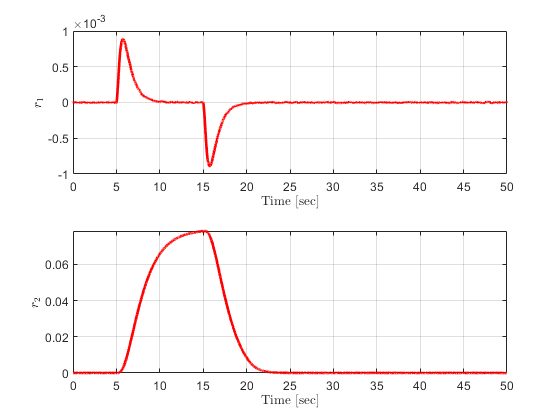

f_m = [0;0;0]; f_m_time = 0;


SIM_TIME = 50;
STEP_SIZE = 0.001;
t = 0:STEP_SIZE:SIM_TIME;
n_t = length(t);


% Inputs
u1 = zeros(n_t,1);
% u1(t>20) = 1;
% u1(t>30) = 0;
% u1(t>35) = -1;
u2 = zeros(n_t,1);
u2(t>5) = 1;
u2(t>15) = 0;
% u2(t>30) = -1;
U = [t', u1, u2];

% Simulation
out = sim('q2_TDO.slx', SIM_TIME, [], U);

% % Residuals
r = out.r.Data;
r1 = r(:,1);
r2 = r(:,2);
t_d = out.r.Time;


figure(1)
subplot(2,1,1)
plot(t_d, r1, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_1$', "interpreter", "latex")

subplot(2,1,2)
plot(t_d, r2, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_2$', "interpreter", "latex")